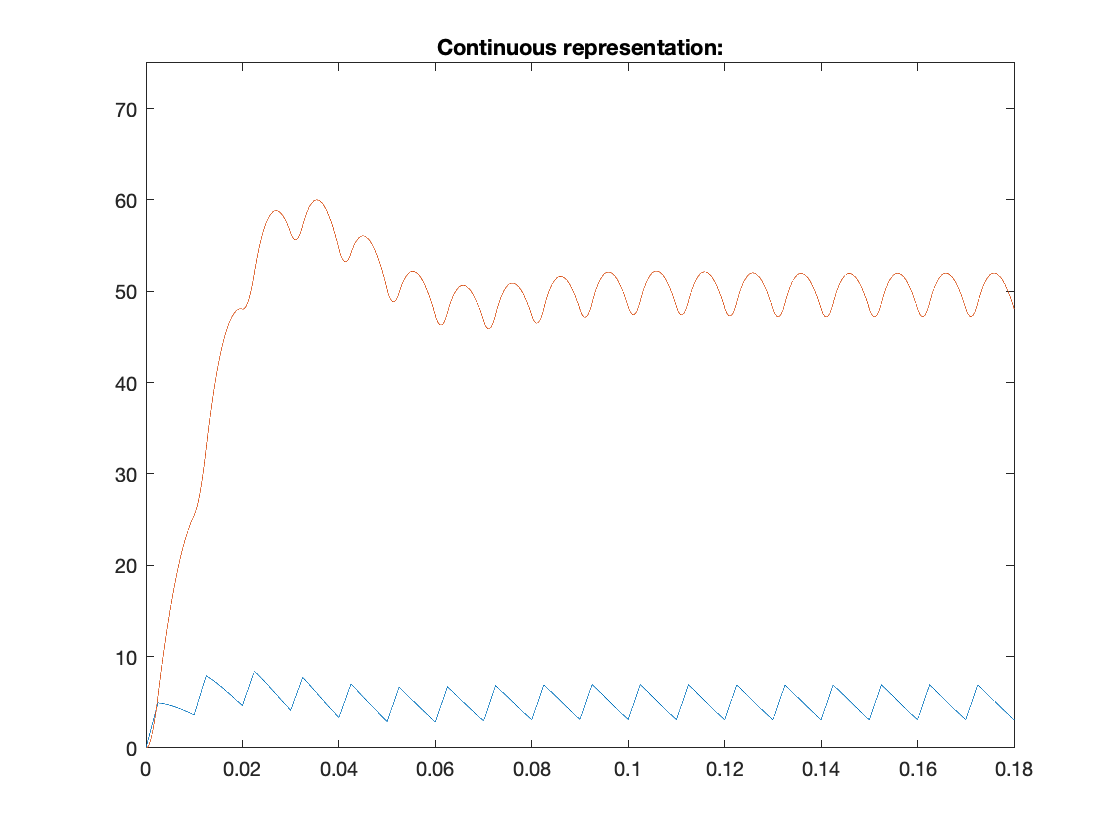

%%Case 2
%%Buck Converter, Resistance increment (10Ohm to 20Ohm)
%
L_1=100e-03; %Coil
C=1000e-06; %Capacitor
R=10; %Resistance
T=0.01; %Duty cycle
V=200; %V_input
time=1.2;%Duration of the control action simmulation
A=[0 -1/L_1; 1/C -1/R/C]; %State matrix "Buck Converter"
B=[V/L_1; 0]; %Input matrix
V_o=0;
I_o=0; %At 10OHm
V_f=50;
I_f=2.3125; %At 20Ohm - this value is T dependant, take it into account when changing T.
%Some reference values: With T=0.001/I_f=2.3125 ; T=0.005/I_f=1.5590
%;T=0.01/If=0.5973
%
%Continuous representation
%
Td=T/4000;
N=1000*(time/T);
delta=0.25;
x=zeros(2,N);
x(:,1)=[I_o;V_o];
for i=1:N+1
    if (mod(i,4000)/4000<delta)
       x(:,i+1)=x(:,i)+Td*(A*x(:,i)+B);
    else
       x(:,i+1)=x(:,i)+ Td*A*x(:,i);
    end
    if (x(1,i+1)<0)
        x(1,i+1)=0;
    end
end
figure
t=[0 (1:N+1)*Td];
plot(t,x')
title('Continuous representation:')
ylim([0 75])
xlim([0 0.18])

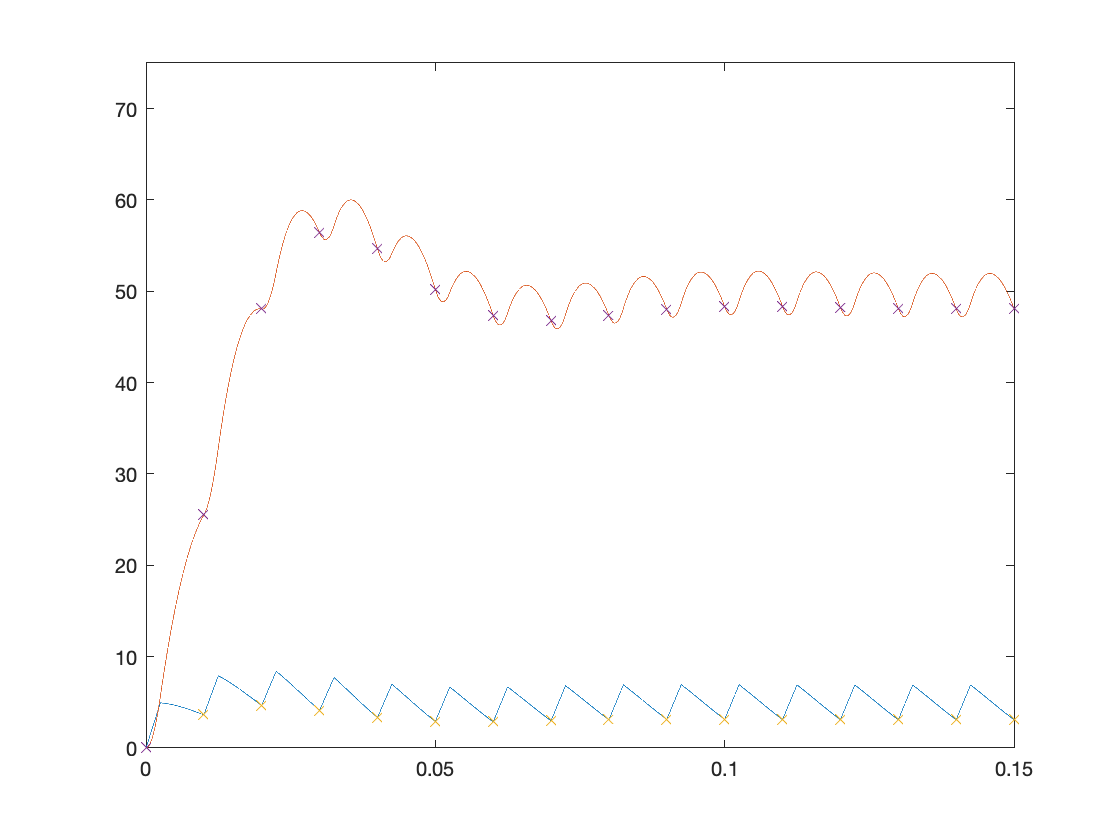

T=0.01;
[PA,PB,alpha2]=discrete_binary_f(A,B,T); %Fuzzy binary discretization function
%%%%%%%
N=50*20; %Number of cycles
x2=zeros(length(A),N);
x2(:,1)=[I_o,V_o]'; %Initial state
alpha=[];
r=rank(A);
for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
%Calculates each X value for each period of time.
for i=1:N+1
    x2(:,i+1)=PA*x2(:,i)+PB.eval(alpha)*delta';
end
t2=[0 (1:N+1)*T];
figure
plot(t,x') 
hold on
plot(t2,x2','x')
hold off
%title('Discret response VS. continuous response:')
ylim([0 75])
xlim([0 0.15])

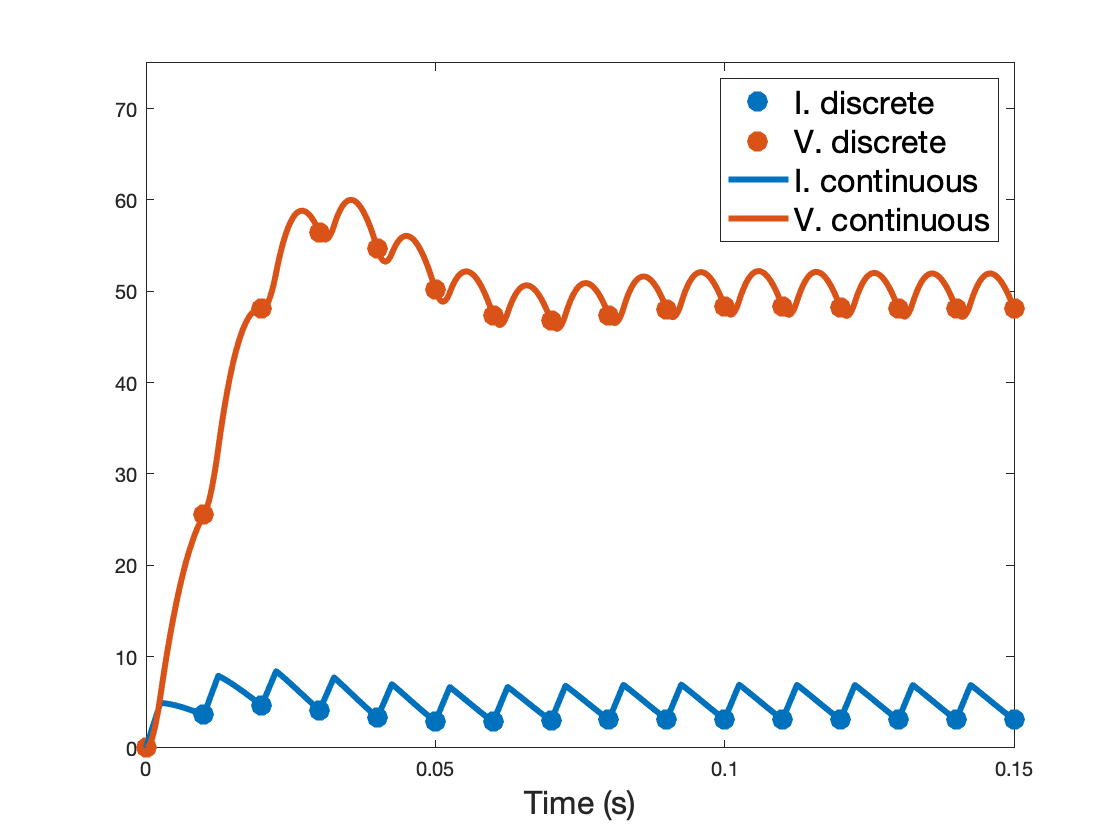

%
%
%
%
figure
t3=[0 (1:N+1)*T];
plot(t3,x2(1,:)','o','MarkerSize',10,'MarkerFaceColor','#0072BD','Color','#0072BD')
hold on
plot(t3,x2(2,:)','o','MarkerSize',10,'MarkerFaceColor','#D95319','Color','#D95319') 
plot(t,x(1,:),'LineWidth',3,'MarkerFaceColor','#0072BD','Color','#0072BD');
plot(t,x(2,:),'LineWidth',3,'MarkerFaceColor','#D95319','Color','#D95319');
hold off 
legend({'I. discrete','V. discrete','I. continuous','V. continuous'},'Location','northeast','FontSize',16)
xlabel({'Time (s)'},'FontSize',16)
ylim([0 75])
xlim([0 0.15])